% Bestehendes trainiertes Netz laden
modelPfad = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren\netGAP32_Lauf_01.mat";
load(modelPfad, "net");


% %% Alte Trainingsdaten laden
% ordnerAlt = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\Tem30uOhneGlei";
% 
% imdsAlt = imageDatastore(ordnerAlt, ...
%     "IncludeSubfolders", true, ...
%     "LabelSource", "foldernames");


%% Neue Trainingsdaten laden
ordnerNeu = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTrainingNeueVorverarbeitungMischDatenSatz";

imdsNeu = imageDatastore(ordnerNeu, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");


%% Sicherstellen, dass die Klassen gleich sind
% classNames = categories(imdsAlt.Labels);

% imdsAlt.Labels = categorical(string(imdsAlt.Labels), classNames);
% imdsNeu.Labels = categorical(string(imdsNeu.Labels), classNames);

if any(isundefined(imdsNeu.Labels))
    error("Die neuen Daten enthalten Klassenordner, die nicht zu den alten Klassen passen.");
end


%% Alte + neue Daten zusammenführen
% alleDateien = [imdsAlt.Files; imdsNeu.Files];
% alleLabels  = [imdsAlt.Labels; imdsNeu.Labels];


alleDateien = [imdsNeu.Files];
alleLabels  = [ imdsNeu.Labels];

imdsGesamt = imageDatastore(alleDateien);
imdsGesamt.Labels = alleLabels;


%% Optional: Datensatz wieder balancieren
% labelCount = countEachLabel(imdsGesamt);
% numPerLabel = min(labelCount.Count);
% 
% imdsBalanced = splitEachLabel(imdsGesamt, numPerLabel, "randomized");
labelCount = countEachLabel(imdsGesamt);
disp(labelCount);

                  Label                   Count
    __________________________________    _____

    Achtung_Gefahrenstelle                  71 
    BilderOhneSchilder                     526 
    Durchfahrt_Verboten_Einbahnstrasse      60 
    Fussgaengerueberweg                     80 
    Geschwindigkeitsbegrenzung_100          60 
    Geschwindigkeitsbegrenzung_30           60 
    Geschwindigkeitsbegrenzung_50           56 
    Geschwindigkeitsbegrenzung_70           63 
    Geschwindigkeitsempfehlung_30           65 
    Geschwindigkeitsempfehlung_90           50 
    Stoppschild                             37 
    Verkehrsberuhigter_Bereich              52 
    Vorfahrt_Achten                         39 



    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00        5e-05                            2.5689                                    47.737
            1        1       00:00:00        5e-05          3.2168                                    50                      
           50        1       00:00:05        5e-05          2.2038             1.688               56.25                60.905
          100        2       00:00:06        5e-05          1.3115            1.4446               56.25                62.551
          150        3       00:00:08        5e-05         0.76404            1.3095               68.75                66.255
          200        4       00:00:09        5e-05         0.51638            1.1809               81.25       

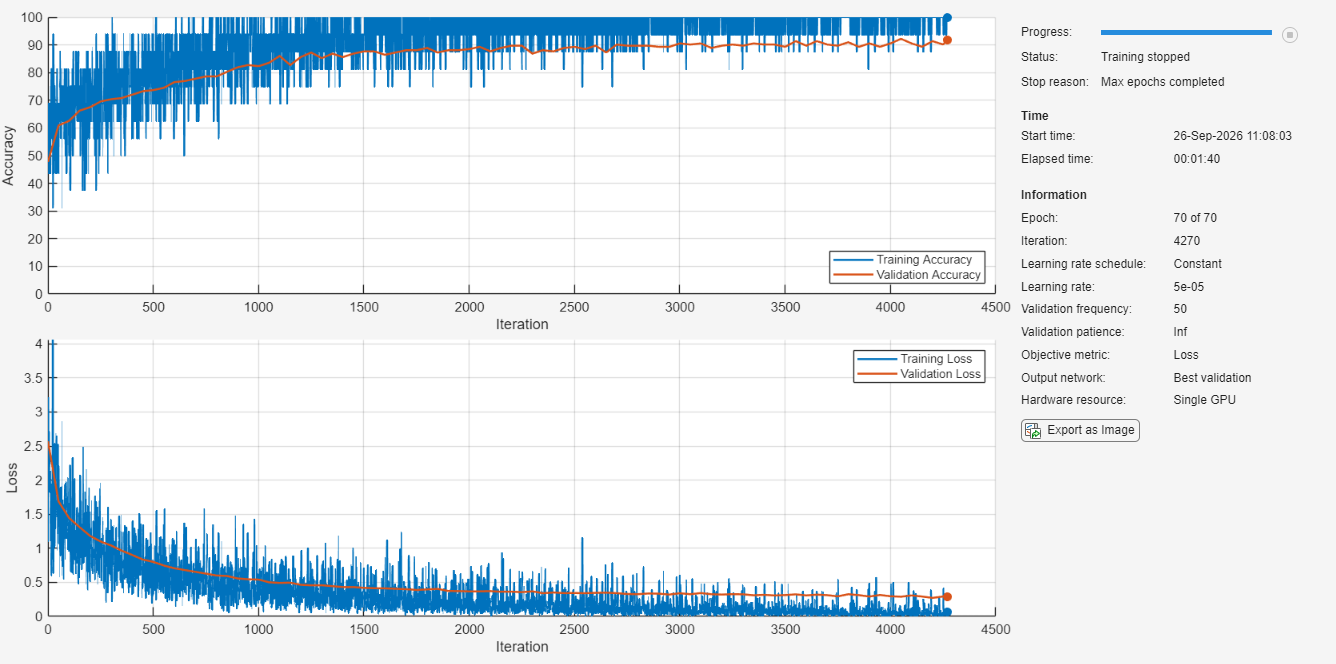


%% Trainings- und Validierungsdaten erzeugen
[imdsTrainWeiter, imdsValidationWeiter] = splitEachLabel(imdsGesamt, 0.8, "randomized");


%% Augmented Datastores
augTrainWeiter = augmentedImageDatastore([48 48 3], imdsTrainWeiter, ...
    "ColorPreprocessing", "none", ...
    "OutputSizeMode", "resize");

augValWeiter = augmentedImageDatastore([48 48 3], imdsValidationWeiter, ...
    "ColorPreprocessing", "none", ...
    "OutputSizeMode", "resize");


%% Trainingsoptionen fürs Weitertrainieren
% Wichtig: kleinere Lernrate als beim ersten Training
optionsWeiter = trainingOptions("adam", ...
    "MaxEpochs", 70, ...
    "InitialLearnRate", 0.00005, ...
    "MiniBatchSize", 16, ...
    "Shuffle", "every-epoch", ...
    "ValidationData", augValWeiter, ...
    "Plots", "training-progress", ...
    "Metrics", "accuracy");


%% Bestehendes Netz weitertrainieren
net = trainnet(augTrainWeiter, net, "crossentropy", optionsWeiter);

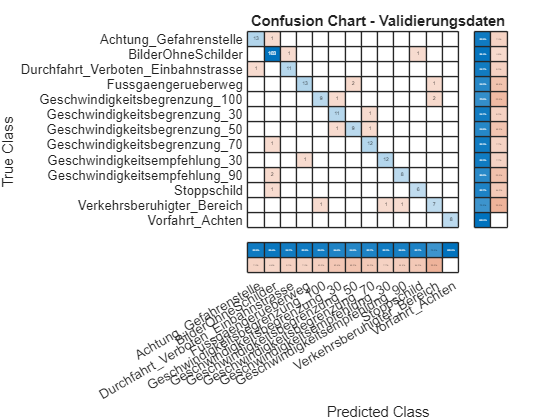

Validierungsdaten Accuracy: 91.36 %
Falsch erkannte Bilder in Validierungsdaten: 21 von 243
                                                                                                       Datei                                                                                                                    Richtig                              Vorhersage                KonfidenzProzent
    ___________________________________________________________________________________________________________________________________________________________________________________________________________    __________________________________    __________________________________    ________________

    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTrainingNeueVorverarbeitungMischDatenSatz\Achtung_Gefahrenstelle\bil

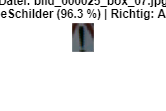

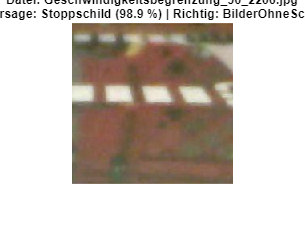

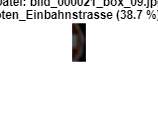

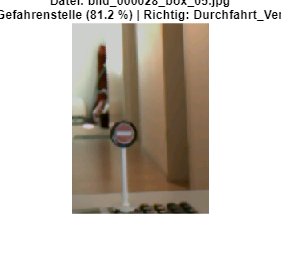

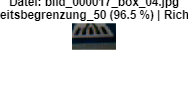

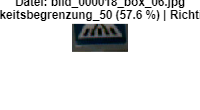

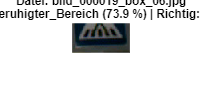

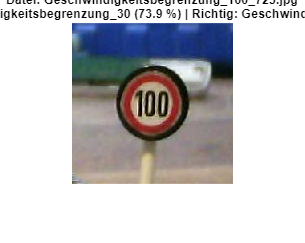



%% Weitertrainiertes Netz speichern
save("meinNetz_weitertrainiertGroßMisch.mat", "net");



% Validierungsdatensatz auswerten
[YPredVal, accVal, confVal, falschVal] = confusionchartMitFehlern( ...
    net, ...
    augValWeiter, ...
    imdsValidationWeiter, ...
    "Validierungsdaten", ...
    30);   % maximal 30 falsche Bilder anzeigen

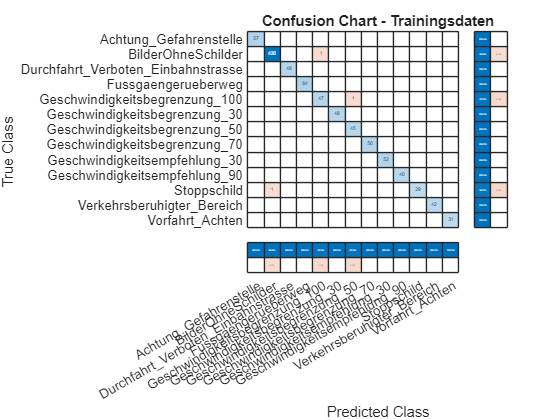

Trainingsdaten Accuracy: 99.69 %
Falsch erkannte Bilder in Trainingsdaten: 3 von 976
                                                                                               Datei                                                                                                          Richtig                          Vorhersage              KonfidenzProzent
    ___________________________________________________________________________________________________________________________________________________________________________________________    ______________________________    ______________________________    ________________

    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTrainingNeueVorverarbeitungMischDatenSatz\BilderOhneSchilder\bild_000037_box_17.jpg"                BilderOhneSchilder     

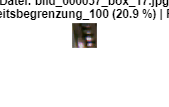

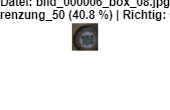

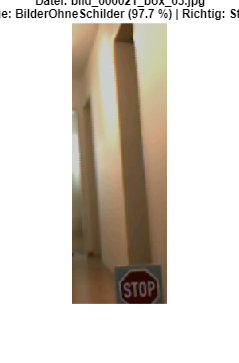



% Optional: Trainingsdatensatz ebenfalls auswerten
[YPredTrain, accTrain, confTrain, falschTrain] = confusionchartMitFehlern( ...
    net, ...
    augTrainWeiter, ...
    imdsTrainWeiter, ...
    "Trainingsdaten", ...
    30);




function [YPred, accuracy, confMat, falschTbl] = confusionchartMitFehlern(net, augDS, imdsOriginal, titel, maxBilder)

    if nargin < 5
        maxBilder = 20;
    end

    %% Wahre Labels und Klassennamen
    trueLabels = imdsOriginal.Labels;
    classNames = categories(trueLabels);

    %% Bilder aus augmentedImageDatastore lesen
    tbl = readall(augDS);
    imgs = tbl{:,1};

    X = cat(4, imgs{:});
    X = single(X);

    %% Vorhersage berechnen
    scores = minibatchpredict(net, X);
    scores = squeeze(scores);

    % Erwartet wird: Klassen x Bilder
    if size(scores,1) ~= numel(classNames)
        scores = scores';
    end

    %% Vorhergesagte Klasse bestimmen
    YPred = onehotdecode(scores, classNames, 1);
    YPred = YPred(:);

    %% Confidence der vorhergesagten Klasse
    [confidence, ~] = max(scores, [], 1);
    confidence = confidence(:);

    %% Confusion Chart
    figure;
    cm = confusionchart(trueLabels, YPred);
    
    cm.Title = "Confusion Chart - " + titel;
    
    % Absolute Trefferzahlen innerhalb der Matrix
    cm.Normalization = "absolute";
    
    % Rechts neben jeder Zeile:
    % Anteil korrekt/inkorrekt = Recall
    cm.RowSummary = "row-normalized";
    
    % Unter jeder Spalte:
    % Anteil korrekt/inkorrekt = Precision
    cm.ColumnSummary = "column-normalized";

    %% Accuracy berechnen
    confMat = confusionmat(trueLabels, YPred);
    accuracy = sum(diag(confMat)) / sum(confMat(:));

    fprintf("%s Accuracy: %.2f %%\n", titel, accuracy * 100);

    %% Falsche Vorhersagen finden
    wrongIdx = find(YPred ~= trueLabels);

    fprintf("Falsch erkannte Bilder in %s: %d von %d\n", ...
        titel, numel(wrongIdx), numel(trueLabels));

    %% Tabelle mit falschen Vorhersagen erzeugen
    falschTbl = table( ...
        string(imdsOriginal.Files(wrongIdx)), ...
        trueLabels(wrongIdx), ...
        YPred(wrongIdx), ...
        confidence(wrongIdx) * 100, ...
        'VariableNames', {'Datei', 'Richtig', 'Vorhersage', 'KonfidenzProzent'} ...
    );

    disp(falschTbl);

    %% Falsch erkannte Bilder anzeigen
    anzahlAnzeigen = min(maxBilder, numel(wrongIdx));

    for i = 1:anzahlAnzeigen

        idx = wrongIdx(i);
        img = readimage(imdsOriginal, idx);

        figure;
        imshow(img);

        [~, name, ext] = fileparts(imdsOriginal.Files{idx});

        title(sprintf("Falsch erkannt\nDatei: %s%s\nVorhersage: %s (%.1f %%) | Richtig: %s", ...
            name, ext, ...
            string(YPred(idx)), ...
            confidence(idx) * 100, ...
            string(trueLabels(idx))), ...
            "Interpreter", "none");
    end

end